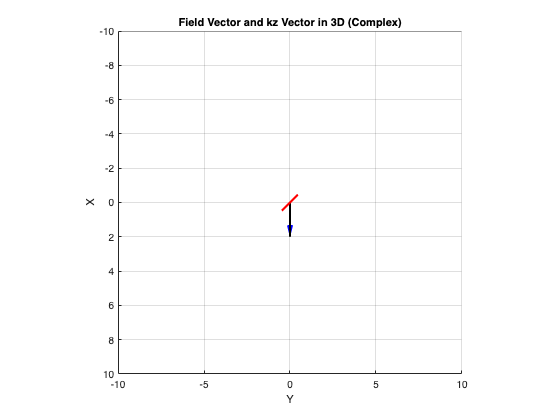

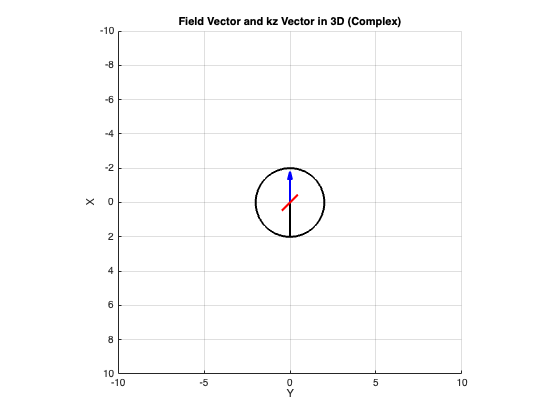

% Set up the figure
figure;
axis([-10, 10, -10, 10, -10, 10]);
axis square;
grid on;
hold on;

% Initialize variables
x = 0;  % x-coordinate of the vector
y = 0;  % y-coordinate of the vector
t = 0;
frequency = 1;  % Adjust the frequency of the wave
E = 1 + 1i;  % Complex amplitude of the wave
omega = 2 * pi * frequency;  % Angular frequency

% Calculate the complex field outside the loop
k_z = 1;  % Adjust the value of k_z as desired
z = 0;  % Adjust the value of z as desired
complex_field_x = 2  * exp(-1i * k_z * z);
complex_field_y = 2*i *  exp(-1i * k_z * z);

% Store the positions for plotting
positions = [x; y; t];

% Main loop
while true
    % Calculate the vector components
    Ex = real(complex_field_x * exp(1i * omega * t));
    Ey = real(complex_field_y * exp(1i * omega * t));
    Ez = 0;  % No component in the z-direction for the field vector
    
    % Calculate the vector for kz direction
    kx = 0;  % No component in the x-direction for kz vector
    ky = 0;  % No component in the y-direction for kz vector
    kz_vector = omega;
    
    % Plot the field vector
    quiver3(x, y, t, Ex, Ey, Ez, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.8);
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Field Vector and kz Vector in 3D (Complex)');
    
    % Plot the kz vector
    quiver3(x, y, t, kx, ky, kz_vector, 'r', 'LineWidth', 2, 'MaxHeadSize', 1);
    
    % Calculate the end point of the vector
    end_x = x + Ex;
    end_y = y + Ey;
    end_z = t + Ez;
    
    % Store the new position
    positions = [positions, [end_x; end_y; end_z]];
    
    % Draw the plot using stored positions
    plot3(positions(1, :), positions(2, :), positions(3, :), 'k', 'LineWidth', 2);
    
    % Adjust the plot view and scaling
    view(90, 90);  % Rotate the view to see the x-y plane
    
    % Update the time variable
    t = t + 0.01;  % Adjust the time step as desired
    
    % Pause to control the animation speed
    pause(0.01);  % Adjust the pause duration as desired
    
    % Clear the previous plot
    cla;
end